# Train Generative Adversarial Network (GAN)

This example shows how to train a generative adversarial network (GAN) to generate images.

A generative adversarial network (GAN) is a type of deep learning network that can generate data with similar characteristics as the input training data.

A GAN consists of two networks that train together:

- The generator - Given a vector or random values as input, this network generates data with the same structure as the training data.

- The discriminator - Given batches of data containing observations from both the training data, and generated data from the generator, this network attempts to classify the observations as "real" or "generated".

To train a GAN, train both networks simultaneously to maximize the performance of both:

- Train the generator to generate data that "fools" the discriminator.

- Train the discriminator to distinguish between real and generated data.

To maximize the performance of the generator, maximize the loss of the discriminator when given generated data. That is, the objective of the generator is to generate data that the discriminator classifies as "real".

To maximize the performance of the discriminator, minimize the loss of the discriminator when given batches of both real and generated data. That is, the objective of the discriminator is to not be "fooled" by the generator.

Ideally, these strategies result in a generator that generates convincingly realistic data and a discriminator that has learned strong feature representations that are characteristic of the training data.

## Load Training Data

Download and extract the [Flowers](https://www.tensorflow.org/datasets/datasets#tf_flowers) dataset [1].


downloadFolder = "G:\GAN\flower_dataset\";
filename = fullfile(downloadFolder,'flower_dataset.tgz');
imageFolder = fullfile(downloadFolder,'flower_photos');

Create an image datastore containing the photos of sunflowers only.

datasetFolder = fullfile(imageFolder,"roses");

imds = imageDatastore(datasetFolder, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

Augment the data to include random horizontal flipping, scaling, and resize the images to have size 64-by-64. 

augmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandScale',[1 2]);
augimds = augmentedImageDatastore([64 64],imds,'DataAugmentation',augmenter);

## Define Generator Network

Define a network that generates images from 1-by-1-by-100 arrays of random values. Create a network that upscales 1-by-1-by-100 arrays to 64-by-64-by-3 arrays using a series of transposed convolution layers with batch normalization and ReLU layers.

- For the transposed convolution layers, specify 4-by-4 filters with a decreasing number of filters for each layer.

- For the second transposed convolution layer onwards, specify a stride of 2 and to crop the output by one pixel on each edge.

- For the final transposed convolution layer, specify 3 filters which correspond to the RGB channels of the generated images.

- At the end of the network, include a tanh layer.

filterSize = [4 4];
numFilters = 64;
numLatentInputs = 100;

layersGenerator = [
    imageInputLayer([1 1 numLatentInputs],'Normalization','none','Name','in')
    transposedConv2dLayer(filterSize,8*numFilters,'Name','tconv1')
    batchNormalizationLayer('Name','bn1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(filterSize,4*numFilters,'Stride',2,'Cropping',1,'Name','tconv2')
    batchNormalizationLayer('Name','bn2')
    reluLayer('Name','relu2')
    transposedConv2dLayer(filterSize,2*numFilters,'Stride',2,'Cropping',1,'Name','tconv3')
    batchNormalizationLayer('Name','bn3')
    reluLayer('Name','relu3')
    transposedConv2dLayer(filterSize,numFilters,'Stride',2,'Cropping',1,'Name','tconv4')
    batchNormalizationLayer('Name','bn4')
    reluLayer('Name','relu4')
    transposedConv2dLayer(filterSize,3,'Stride',2,'Cropping',1,'Name','tconv5')
    tanhLayer('Name','tanh')];

lgraphGenerator = layerGraph(layersGenerator);

To train the network with a custom training loop and enable automatic differentiation, convert the layer graph to a `dlnetwork` object.

dlnetGenerator = dlnetwork(lgraphGenerator)

dlnetGenerator =   dlnetwork - 属性:

         Layers: [15×1 nnet.cnn.layer.Layer]
    Connections: [14×2 table]
     Learnables: [18×3 table]
          State: [8×3 table]


## Define Discriminator Network

Define a network that classifies real and generated 64-by-64 images.

Create a network that takes 64-by-64-by-3 images and inputs and outputs a scalar prediction score using a series of convolution layers with batch normalization and leaky ReLU layers.

- For the convolution layers, specify 4-by-4 filters with an increasing number of filters for each layer.

- For the second convolution layer onwards, specify a stride of 2 and to pad the output by one pixel on each edge.

- For the final convolution layer, specify one 4-by-4 filter so that the network outputs a scalar prediction.

scale = 0.2;

layersDiscriminator = [
    imageInputLayer([64 64 3],'Normalization','none','Name','in')
    convolution2dLayer(filterSize,numFilters,'Stride',2,'Padding',1,'Name','conv1')
    leakyReluLayer(scale,'Name','lrelu1')
    convolution2dLayer(filterSize,2*numFilters,'Stride',2,'Padding',1,'Name','conv2')
    batchNormalizationLayer('Name','bn2')
    leakyReluLayer(scale,'Name','lrelu2')
    convolution2dLayer(filterSize,4*numFilters,'Stride',2,'Padding',1,'Name','conv3')
    batchNormalizationLayer('Name','bn3')
    leakyReluLayer(scale,'Name','lrelu3')
    convolution2dLayer(filterSize,8*numFilters,'Stride',2,'Padding',1,'Name','conv4')
    batchNormalizationLayer('Name','bn4')
    leakyReluLayer(scale,'Name','lrelu4')
    convolution2dLayer(filterSize,1,'Name','conv5')];

lgraphDiscriminator = layerGraph(layersDiscriminator);

To train the network with a custom training loop and enable automatic differentiation, convert the layer graph to a `dlnetwork` object.

dlnetDiscriminator = dlnetwork(lgraphDiscriminator)

dlnetDiscriminator =   dlnetwork - 属性:

         Layers: [13×1 nnet.cnn.layer.Layer]
    Connections: [12×2 table]
     Learnables: [16×3 table]
          State: [6×3 table]


Visualize the generator and discriminator networks in a plot.

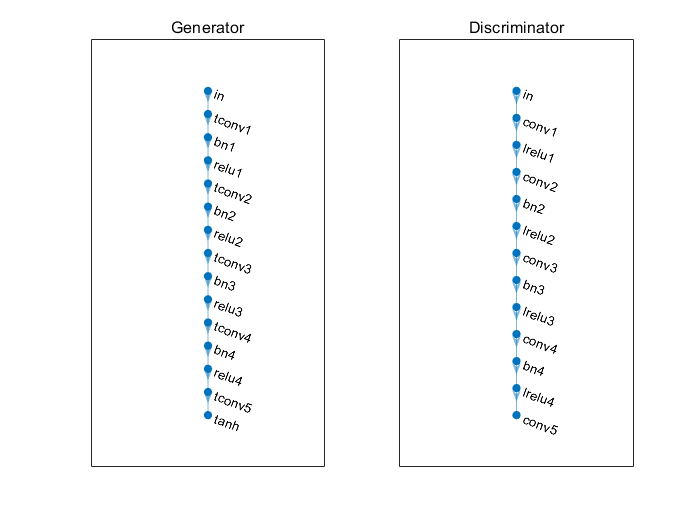

figure
subplot(1,2,1)
plot(lgraphGenerator)
title("Generator")

subplot(1,2,2)
plot(lgraphDiscriminator)
title("Discriminator")

## Define Model Gradients and Loss Functions

Create the function `modelGradients`, listed at the end of the example, that takes generator and discriminator `dlnetwork` objects `dlnetGenerator` and `dlnetDiscrimintor`, a mini-batch of input data `X`, and an array of random values `Z`, and returns the gradients of the loss with respect to the learnable parameters in the networks and an array of generated images.

The objective of the generator is to generate data that the discriminator classifies as "real". To maximize the probability that images from the generator are classified as real by the discriminator, minimize the negative log likelihood function. The loss function for the generator is given by

    
$$\textrm{lossGenerator}=-\textrm{mean}\left(\log \left(\sigma \left({\hat{Y} }_{\textrm{Generated}} \right)\right)\right),$$


where $\sigma$ denotes the sigmoid function, and $\hat{Y}_{Generated}$ denotes the output of the discriminator with generated data input.

The objective of the discriminator is to not be "fooled" by the generator. To maximize the probability that the discriminator successfully discriminates between the real and generated images, minimize the sum of the corresponding negative log likelihood functions. The output of the discriminator corresponds to the probabilities the input belongs to the "real" class. For the generated data, to use the probabilities corresponding to the "generated" class, use the values $1-\sigma(\hat{Y}_{Generated})$. The loss function for the discriminator is given by

    
$$\textrm{lossDiscriminator}=-\textrm{mean}\left(\log \left(\sigma \left({\hat{Y} }_{\textrm{Real}} \right)\right)\right)-\textrm{mean}\left(\log \left(1-\sigma \left({\hat{Y} }_{\textrm{Generated}} \right)\right)\right),$$


where $\hat{Y}_{Real}$ denotes the output of the discriminator with real data input.

## Specify Training Options

Train with a minibatch size of 128 for 1000 epochs. For larger datasets, you might not need to train for as many epochs. Set the read size of the augmented image datastore to the mini-batch size.

numEpochs = 1000;
miniBatchSize = 128;
augimds.MiniBatchSize = miniBatchSize;

Specify the options for ADAM optimization:

- If the discriminator learns to discriminate between real and generated images too quickly, then the generator may fail to train. To better balance the learning of the discriminator and the generator, set the learn rate of the generator to 0.0002 and the learn rate of the discriminator to 0.0001.

- For each network, initialize the trailing average gradient and trailing average gradient-square decay rates with `[]`.

- For both networks, use a gradient decay factor of 0.5 and a squared gradient decay factor of 0.999.

learnRateGenerator = 0.0002;
learnRateDiscriminator = 0.0001;

trailingAvgGenerator = [];
trailingAvgSqGenerator = [];
trailingAvgDiscriminator = [];
trailingAvgSqDiscriminator = [];

gradientDecayFactor = 0.5;
squaredGradientDecayFactor = 0.999;

Train on a GPU if one is available. Using a GPU requires Parallel Computing Toolbox™ and a CUDA® enabled NVIDIA® GPU with compute capability 3.0 or higher.

executionEnvironment = "auto";

## Train Model

Train the model using a custom training loop. Loop over the training data and update the network parameters at each iteration. To monitor the training progress, display a batch of generated images using a held-out array of random values to input into the generator.

For each epoch, shuffle the datastore and loop over mini-batches of data.

For each mini-batch:

- Normalize the data so that the pixels take values in the range [-1, 1].

- Convert the data to `dlarray` objects with underlying type `single` and specify the dimension labels `'SSCB'` (spatial, spatial, channel, batch).

- Generate a `dlarray` object containing an array of random values for the generator network.

- For GPU training, convert the data to `gpuArray` objects.

- Evaluate the model gradients using `dlfeval` and the `modelGradients` function.

- Update the network parameters using the `adamupdate` function.

- After every 100 iterations, display a batch of generated images for a fixed held-out generator input.

To monitor training progress, create a held-out batch of fixed 64 1-by-1-by-100 arrays of random values to input into the generator. Specify the dimension labels `'SSCB'` (spatial, spatial, channel, batch). For GPU training, convert the data to `gpuArray`.

ZValidation = randn(1,1,numLatentInputs,64,'single');
dlZValidation = dlarray(ZValidation,'SSCB');

if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
    dlZValidation = gpuArray(dlZValidation);
end

Train the GAN. This can take some time to run.

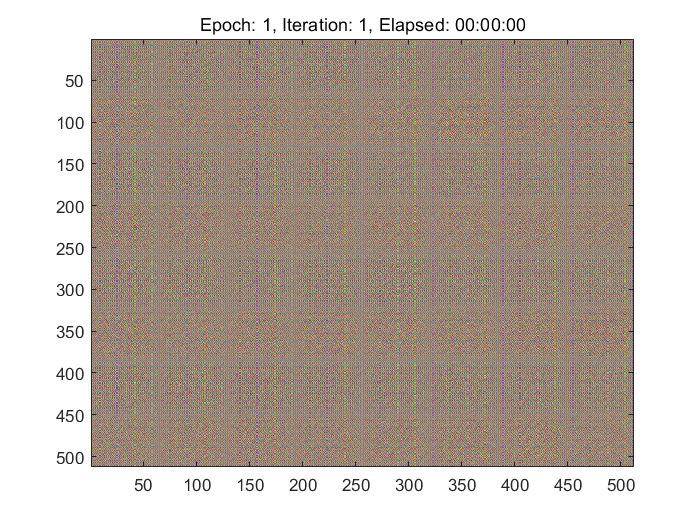

figure
iteration = 0;
start = tic;

% Loop over epochs.
for i = 1:numEpochs
    
    % Reset and shuffle datastore.
    reset(augimds);
    augimds = shuffle(augimds);
    
    % Loop over mini-batches.
    while hasdata(augimds)
        iteration = iteration + 1;
        
        % Read mini-batch of data.
        data = read(augimds);
        
        % Ignore last partial mini-batch of epoch.
        if size(data,1) < miniBatchSize
            continue
        end
        
        % Concatenate mini-batch of data and generate latent inputs for the
        % generator network.
        X = cat(4,data{:,1}{:});
        Z = randn(1,1,numLatentInputs,size(X,4),'single');
        
        % Normalize the images
        X = (single(X)/255)*2 - 1;
        
        % Convert mini-batch of data to dlarray specify the dimension labels
        % 'SSCB' (spatial, spatial, channel, batch).
        dlX = dlarray(X, 'SSCB');
        dlZ = dlarray(Z, 'SSCB');
        
        % If training on a GPU, then convert data to gpuArray.
        if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
            dlX = gpuArray(dlX);
            dlZ = gpuArray(dlZ);
        end
        
        % Evaluate the model gradients and the generator state using
        % dlfeval and the modelGradients function listed at the end of the
        % example.
        [gradientsGenerator, gradientsDiscriminator, stateGenerator] = ...
            dlfeval(@modelGradients, dlnetGenerator, dlnetDiscriminator, dlX, dlZ);
        dlnetGenerator.State = stateGenerator;
        
        % Update the discriminator network parameters.
        [dlnetDiscriminator.Learnables,trailingAvgDiscriminator,trailingAvgSqDiscriminator] = ...
            adamupdate(dlnetDiscriminator.Learnables, gradientsDiscriminator, ...
            trailingAvgDiscriminator, trailingAvgSqDiscriminator, iteration, ...
            learnRateDiscriminator, gradientDecayFactor, squaredGradientDecayFactor);
        
        % Update the generator network parameters.
        [dlnetGenerator.Learnables,trailingAvgGenerator,trailingAvgSqGenerator] = ...
            adamupdate(dlnetGenerator.Learnables, gradientsGenerator, ...
            trailingAvgGenerator, trailingAvgSqGenerator, iteration, ...
            learnRateGenerator, gradientDecayFactor, squaredGradientDecayFactor);
        
        % Every 100 iterations, display batch of generated images using the
        % held-out generator input.
        %if mod(iteration,10) == 0 || iteration == 1
            
            % Generate images using the held-out generator input.
            dlXGeneratedValidation = predict(dlnetGenerator,dlZValidation);
            
            % Rescale the images in the range [0 1] and display the images.
            I = imtile(extractdata(dlXGeneratedValidation));
            I = rescale(I);
            image(I)
            
            % Update the title with training progress information.
            D = duration(0,0,toc(start),'Format','hh:mm:ss');
            title(...
                "Epoch: " + i + ", " + ...
                "Iteration: " + iteration + ", " + ...
                "Elapsed: " + string(D))
            
            drawnow
        %end
    end
end

Here, the discriminator has learned a strong feature representation that identifies real images among generated images and in turn, the generator has learned a similarly strong feature representation that allows it to generate realistic looking data.

## Generate New Images

To generate new images, use the `predict` function on the generator with a `dlarray` object containing a batch of 1-by-1-by-100 arrays of random values. To display the images together, use the `imtile` function and rescale the images using the `rescale` function.

Create a `dlarray` object containing a batch of 16 1-by-1-by-100 arrays of random values to input into the generator network.

ZNew = randn(1,1,numLatentInputs,16,'single');
dlZNew = dlarray(ZNew,'SSCB');

For GPU inference, convert the data to `gpuArray` objects.

if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
    dlZNew = gpuArray(dlZNew);
end

Generate new images using the `predict` function with the generator and the input data.

dlXGeneratedNew = predict(dlnetGenerator,dlZNew);

Display the images.

I = imtile(extractdata(dlXGeneratedNew));
I = rescale(I);
image(I)
title("Generated Images")

## Model Gradients Function

The function `modelGradients` takes generator and discriminator `dlnetwork` objects `dlnetGenerator` and `dlnetDiscrimintor`, a mini-batch of input data `X`, and an array of random values `Z`, and returns the gradients of the loss with respect to the learnable parameters in the networks and an array of generated images.

function [gradientsGenerator, gradientsDiscriminator, stateGenerator] = ...
    modelGradients(dlnetGenerator, dlnetDiscriminator, dlX, dlZ)

% Calculate the predictions for real data with the discriminator network.
dlYPred = forward(dlnetDiscriminator, dlX);

% Calculate the predictions for generated data with the discriminator network.
[dlXGenerated,stateGenerator] = forward(dlnetGenerator,dlZ);
dlYPredGenerated = forward(dlnetDiscriminator, dlXGenerated);

% Calculate the GAN loss
[lossGenerator, lossDiscriminator] = ganLoss(dlYPred,dlYPredGenerated);

% For each network, calculate the gradients with respect to the loss.
gradientsGenerator = dlgradient(lossGenerator, dlnetGenerator.Learnables,'RetainData',true);
gradientsDiscriminator = dlgradient(lossDiscriminator, dlnetDiscriminator.Learnables);

end

## GAN Loss Function

The objective of the generator is to generate data that the discriminator classifies as "real". To maximize the probability that images from the generator are classified as real by the discriminator, minimize the negative log likelihood function. The loss function for the generator is given by

    
$$\textrm{lossGenerator}=-\textrm{mean}\left(\log \left(\sigma \left({\hat{Y} }_{\textrm{Generated}} \right)\right)\right),$$


where $\sigma$ denotes the sigmoid function, and $\hat{Y}_{Generated}$ denotes the output of the discriminator with generated data input.

The objective of the discriminator is to not be "fooled" by the generator. To maximize the probability that the discriminator successfully discriminates between the real and generated images, minimize the sum of the corresponding negative log likelihood functions. The output of the discriminator corresponds to the probabilities the input belongs to the "real" class. For the generated data, to use the probabilities corresponding to the "generated" class, use the values $1-\sigma(\hat{Y}_{Generated})$. The loss function for the discriminator is given by

    
$$\textrm{lossDiscriminator}=-\textrm{mean}\left(\log \left(\sigma \left({\hat{Y} }_{\textrm{Real}} \right)\right)\right)-\textrm{mean}\left(\log \left(1-\sigma \left({\hat{Y} }_{\textrm{Generated}} \right)\right)\right),$$


where $\hat{Y}_{Real}$ denotes the output of the discriminator with real data input.

function [lossGenerator, lossDiscriminator] = ganLoss(dlYPred,dlYPredGenerated)

% Calculate losses for the discriminator network.
lossGenerated = -mean(log(1-sigmoid(dlYPredGenerated)));
lossReal = -mean(log(sigmoid(dlYPred)));

% Combine the losses for the discriminator network.
lossDiscriminator = lossReal + lossGenerated;

% Calculate the loss for the generator network.
lossGenerator = -mean(log(sigmoid(dlYPredGenerated)));

end

## References

- The TensorFlow Team. *Flowers* [http://download.tensorflow.org/example_images/flower_photos.tgz](http://download.tensorflow.org/example_images/flower_photos.tgz) 

*Copyright 2019 The MathWorks, Inc.*